# Saving files (regular and gif)

clear; clc;

## Create figures

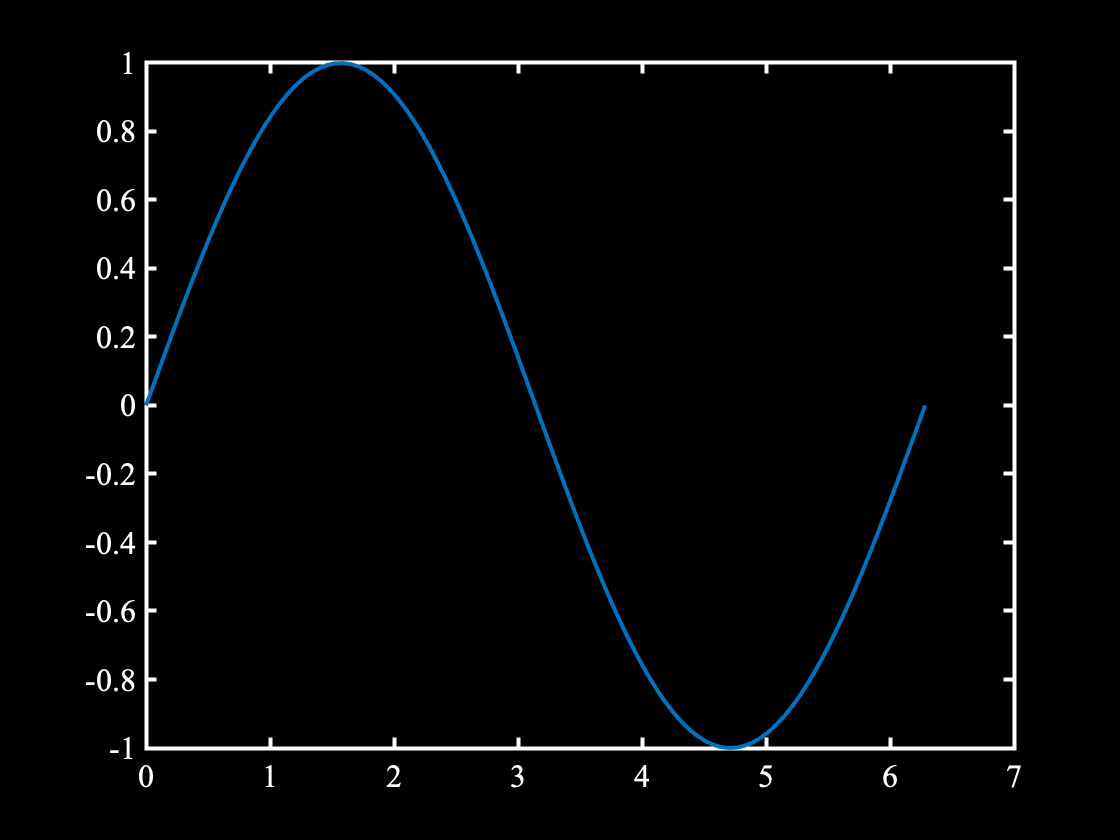

x = linspace(0, 2*pi, 100); % to evaluate

% visualize
figure(); 
plot(x, sin(x), 'linewidth', 2);
auto_save('testFig1', 'close_after',false) % no specification 
% custom folder on working directory level 
auto_save('testFig1', 'close_after',false, 'custom_folder','level1', 'folder_level',1); 
% custom folder on figure directory level 
auto_save('testFig1', 'close_after',false, 'custom_folder','level2', 'folder_level',2); 
% custom folder on date directory level 
darkBackground(); 
auto_save('testFig1', 'close_after',false, 'custom_folder','level3', 'folder_level',3); 

## Create gifs

x_end = linspace(2*pi, 4*pi, 100); % make look bigger 

figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif1.gif', i)
end
% level 1 (black background exmaple)
figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    darkBackground();
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif1.gif', i, 'custom_folder','level1', 'folder_level',1, 'bg_color', [0 0 0])
end
% level 2
figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif1.gif', i, 'custom_folder','level2', 'folder_level',2)
end

% level 3
figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif1.gif', i, 'custom_folder','level3', 'folder_level',3)
end